# Battery testing, modelling, and state estimation - SOC estimation seminar, second part

*David Vošahlík, Tomáš Haniš*

Battery State of Charge (SOC) estimation will today's main target. It is one of the most important battery states, which is, unfortunatelly, not measurable directly. Therefore, SOC has to be estimated. There are many methods ranging from very simple ones like various lookup tables for the output voltage, through coulomb counting method up to more advanced model-based methods like Kalman Filter (KF) algorithm or its non-linear versions such as Extended Kalman Filter (EKF) or Unscented Kalman FIlter (UKF). There exists also many other KF variants but the most used variants for battery SOC estimation (KF, EKF, UKF) has been already mentioned.

## EKF SOC estimation method

#### 2RC model discretization

Your task will be at first develop a discrete time 2RC model, which will be then used to develop the EKF estimation method.

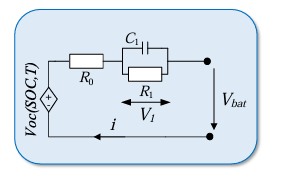

Use the measured data to validate correctness of the battery model implementation.

set(groot, 'defaultTextInterpreter', 'latex')
export_figures = true;
% The model input is current i, assume only the 25 deg C temperature (3rd row in the parameters)
Bat = InitializeBatPars();              % Setup the constants
% Load the measured data
[Time, Current, Voltage, SoC_ref] = load_data();

plot(Time, Current);
grid on;
xlabel('Time [s]')
ylabel('Current [A]');
if export_figures
    exportgraphics(gcf, "figures/validation-I.eps");
end


Ts = 0.1; % Sampling period

n = 3; % Three states
m = 1; % One input
p = 1; % One output
N = length(Time); % Number of samples

u = Current;
y = Voltage;

x_sim = zeros(n, N);
y_sim = zeros(p, N);

x_sim(:, 1) = [0;0; SoC_ref(1)]; % Set the correct initial condition

% Verify that signals match the model
for k = 1:N-1
    % Forward Euler discretization ... x_next = x + Ts * f(x, u)
    % f is the continuous time state derivative function
    x_sim(:, k+1) = x_sim(:, k) + Ts * f(x_sim(:, k), u(:, k), Bat);
    y_sim(:, k) = g(x_sim(:, k), u(:, k), Bat);
end
y_sim(:, N) = g(x_sim(:, N), u(:, N), Bat);

plot(Time, [SoC_ref; x_sim(3, :)], linewidth=2);
xlabel('Time [s]');
ylabel('SoC [\%]');
legend('Reference SoC', 'Simulated SoC')
grid on;
if export_figures
    exportgraphics(gcf, "figures/validation-soc.eps");
end

plot(Time, [y; y_sim], linewidth=2);
xlabel('Time [s]');
ylabel('Voltage [V]');
legend('Reference output', 'Simulated output')
grid on;
if export_figures
    exportgraphics(gcf, "figures/validation-U.eps");
end

y_noise = y - y_sim;
[c, lags] = xcorr(y_noise);
xcorr_peak = c(lags == 0);
plot(lags, c / xcorr_peak, linewidth=2, Marker="x", MarkerSize=10);
hold on;
yline([-1 1] * 5e-2, ':', linewidth=2);
legend('Autocorrelation', '', '5 % threshold')
hold off
xlabel('Lag [-]');
ylabel('Normalized correlation [-]')
grid on
if export_figures
    exportgraphics(gcf, "figures/validation-pred-error.eps");
end
a1 = gca;
fig = figure;
a2 = copyobj(a1, fig);

xlim([-10 10])
if export_figures
    exportgraphics(fig, "figures/validation-pred-error-detail.eps");
end


plot(1:100, polyval(Bat.OCV_polynomial, 1:100), LineWidth=2);
grid on;
xlabel('SoC [\%]');
ylabel('$U_{OC}$ [V]');
yyaxis right
plot(1:100, polyval(polyder(Bat.OCV_polynomial), 1:100), LineWidth=2);
grid on;
xlabel('SoC [\%]');
ylabel('$\frac{\partial U_{OC}}{\partial SoC}$ [V/\%]');
legend("Cell's OCV curve", "Derivative of OCV curve", location='best')

if export_figures
    exportgraphics(fig, "figures/ocv_to_soc.eps");
end

figure

#### EKF implementation

Your second task will be to implement the EKF. EKF has two essential parts. There is a data step and time step. The data step is defined as:


$$\begin{array}{l}
\hat{x} \left(t|t\right)=\hat{x} \left(t|t-1\right)+P\left(t|t-1\right)C^T \left(t\right){\left(C\left(t\right)P\left(t|t-1\right)C^T \left(t\right)+R\right)}^{-1} \left(y\left(t\right)-g\left(\hat{x} \left(t|t-1\right),u\left(t-1\right)\right)\right)\\
P\left(t|t\right)=P\left(t|t-1\right)-P\left(t|t-1\right)C^T \left(t\right){\left(C\left(t\right)P\left(t|t-1\right)C^T \left(t\right)+R\right)}^{-1} C\left(t\right)P\left(t|t-1\right)
\end{array}$$


The data step is also sometimes called the correction step

Then, the time step is defined as:


$$\begin{array}{l}
\hat{x} \left(t+1|t\right)=f\left(\hat{x} \left(t|t\right),u\left(t\right)\right)\\
P\left(t+1|t\right)=A\left(t\right)P\left(t|t\right)A^T \left(t\right)+Q
\end{array}$$


where the system matrices A and C (sometimes called jacobians) are defined as:


$$A\left(t\right)=\frac{\partial f\left(\hat{x} \left(t|t\right),u\left(t\right)\right)}{\partial x},\;\;C\left(t\right)=\frac{\partial g\left(\hat{x} \left(t|t-1\right),u\left(t\right)\right)}{\partial x}$$
 

To sum up. Implement 3 basic things:

- data step

- time step

- jacobians

The time step for P is an approximation that preserves normal disctribution. Nonlinear mapping on P would change the distribution! We have to live with the approximation as it is the best thing we have.

% Implement EKF SOC estimation method

% Tuning of Q and R matrices:
% 1) We initially know nothing about the system, so set Q and R unity and
% observe that the estimate probably trusts the measurement too much->
% increase covariance of measurement.
% 2) Since we know the the structure of the model, we know that the Kalman
% filter should move SoC a lot (that is the uncertain part) and "trust"
% model when it comes to polarization voltages U1, U2

% It is best to keep values in Q and R not very far from the order of
% values of corresponding states/outputs, roughly 3 orders of magnitude at
% most works the best.
R = var(y_noise); % Measurement noise - what errors the y measurement is subject to
Q = diag([1e-12 1e-12 1e-4]); % Process noise - what we have not modelled and is present in the data
% For zero input, the system is not very excited and we can't expect good
% observability / estimate accuracy.

Ts = 0.1;
u = Current;
y = Voltage;
SoC0 = 80;

[x_hat, y_hat] = run_EKF(u, y, Ts, [0;0; SoC0], R, Q, Bat);
[x_hat_perfect_x0, ~] = run_EKF(u, y, Ts, [0;0; SoC_ref(1)], R, Q, Bat);

plot(Time, [SoC_ref; x_hat(3, :)], linewidth=2);
xlabel('Time [s]');
ylabel('SoC [\%]');
grid on;
legend('Reference', 'EKF Estimate', location='best');
if export_figures
    exportgraphics(gcf, "figures/ekf-soc.eps");
end

plot(Time, [y; y_sim; y_hat], linewidth=2);
xlabel('Time [s]');
ylabel('Voltage [V]');
grid on;
legend('Noisy reference U_{bat}', 'Noiseless reference U_{bat}', 'EKF-predicted y_hat', location='best')
ylim([2.9 3.6])
if export_figures
    exportgraphics(gcf, "figures/ekf-U.eps");
end

y_error = y_sim - y_hat;
rms(y_error)

ans = 0.0160

rms(y_error(Time > 10))

ans = 0.0041

#### Homework - Comparison of all approaches

As your homework, you will have to submit a report, where you will compare (qualitatively - figures and quantitatively - statistics like RMSE) all the estimation methods, which we went through, i.e, the open circuit voltage, coulomb counting, their combination and EKF.

%Compare all methods
[SoC_combined, resets] = combined_method(Current, Voltage, 300, Ts, SoC0, Bat);
SoC_cc = cc_method(Current, Ts, SoC0, Bat);
SoC_ocv = ocv_method(Voltage, 240, Ts, Bat);
SoC_EKF = x_hat(3, :);
SoC_EKF_perfect_x0 = x_hat_perfect_x0(3, :);


plot(Time, [SoC_EKF; SoC_EKF_perfect_x0; SoC_combined; SoC_ocv; SoC_cc; SoC_ref], LineWidth=2);
xlabel('Time [s]')
ylabel('SoC [\%]')
grid on;
legend('EKF estimate', 'EKF with perfect x_0', 'Combined method', 'OCV lookup','Coulomb counting', 'Reference signal', location='best');
if export_figures
    exportgraphics(gcf, "figures/comparison.eps");
end

plot(Time, [SoC_EKF; SoC_EKF_perfect_x0; SoC_combined; SoC_ocv; SoC_cc] - SoC_ref, LineWidth=2);
xlabel('Time [s]')
ylabel('SoC error [\%]')
grid on;
legend('EKF estimate', 'EKF with perfect x_0', 'Combined method', 'OCV lookup','Coulomb counting', location='northeast');
if export_figures
    exportgraphics(gcf, "figures/comparison-dev.eps");
end


calculate_rmse = @(signal, start) rms(SoC_ref(Time > start) - signal(Time > start));
RMSE_EKF = calculate_rmse(SoC_EKF, 1)

RMSE_EKF = 6.4523

RMSE_EKF_perfect_x0 = calculate_rmse(SoC_EKF_perfect_x0, 1)

RMSE_EKF_perfect_x0 = 1.1903

RMSE_combined = calculate_rmse(SoC_combined, 1)

RMSE_combined = 6.6171

RMSE_cc = calculate_rmse(SoC_cc, 1)

RMSE_cc = 15.1057

RMSE_ocv = calculate_rmse(SoC_ocv, 1)

RMSE_ocv = 2.9267


T_convergence = 2000;
RMSE_EKF_conv = calculate_rmse(SoC_EKF, T_convergence)

RMSE_EKF_conv = 1.3824

RMSE_EKF_perfect_x0_conv = calculate_rmse(SoC_EKF_perfect_x0, T_convergence)

RMSE_EKF_perfect_x0_conv = 1.4012

RMSE_combined_conv = calculate_rmse(SoC_combined, T_convergence)

RMSE_combined_conv = 1.2323

RMSE_cc_conv = calculate_rmse(SoC_cc, T_convergence)

RMSE_cc_conv = 15.0467

RMSE_ocv_conv = calculate_rmse(SoC_ocv, T_convergence)

RMSE_ocv_conv = 3.1416

function A = dfdx(x, u, Bat, Ts)
% Compute the discrete time jacobian of the system derivative function with respect to state (system matrix A)
% For discrete function x(k+1) = fd(x(k)) = x(k) + Ts * fc(x(k)), the jacobian is eye + Ts * jacobian(fc)
jacobian_continuous = diag([-1 / (Bat.R1 * Bat.C1); -1/(Bat.R2 * Bat.C2); 0]);
A = eye(length(x)) + Ts * jacobian_continuous;
end

function C = dgdx(x,u,Bat, Ts)
% Compute the discrete time jacobian of the output function with respect to state (system matrix C)
dydSOC = polyval(polyder(Bat.OCV_polynomial), x(3));
C = [-1, -1, dydSOC];
end

function [y_bat] = g(x_bat, u_bat, Bat)
% output function for battery - continuous time dynamics
% x_bat - is the battery state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the battery input [Current [A]]
% y_bat - is the battery output [Terminal voltage [V]]
% car - structure with the parameters. Check InitializeCar.m function

% Compute the terminal voltage output. Use the constants defined in the car.Bat
y_bat = ocv_from_soc(x_bat(3), Bat) - x_bat(1) - x_bat(2) - u_bat*Bat.R0;
end

function [xDot_bat] = f(x_bat, u_bat, Bat)
% State derivative function for battery - continuous time dynamics
% x_bat - is the state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the input [Current [A]]
% car - structure with the parameters. Check InitializeCar.m function

% Implement the continuous time dynamic equations. Use the constants defined in the car.Bat
U1_dot = -1/(Bat.R1*Bat.C1)*x_bat(1) + 1/Bat.C1*u_bat(1);
U2_dot = -1/(Bat.R2*Bat.C2)*x_bat(2) + 1/Bat.C2*u_bat(1);
% TODO incorrectly divided C by 36 instead of multiplying
SOC_dot = -1/(Bat.C/36)*u_bat(1);

% Sort the derivative values to the vector
xDot_bat = [U1_dot;U2_dot;SOC_dot];
end

function voltage = ocv_from_soc(SOC, Bat)
% Copmute the open circuit voltage [V] for the provided SOC [%]
voltage = 2.353 + 0.09131*SOC - 0.003962*SOC.^2 + 8.231e-05*SOC.^3 - 8.089e-07*SOC.^4 + 3.036e-09*SOC.^5;
%assert(abs(voltage - polyval(Bat.OCV_polynomial, SOC)) < 1e-6);
end

function SoC = soc_from_ocv(Voltage, Bat)
    polynomial = Bat.OCV_polynomial;
    polynomial(end) = polynomial(end) - Voltage;
    SoC = roots(polynomial);
    SoC = SoC(imag(SoC) == 0); % Take only the real solution
end

function Bat = InitializeBatPars()

% Battery parameters (only for 25 deg C)
Bat.R1 = 0.045;
Bat.R2 = 0.13;
Bat.C1 = 180;
Bat.C2 = 1790;
% capacity [Ah]
Bat.C = 3;
% internal resistance [Ohm]
Bat.R0 = 0.0013;

Bat.OCV_polynomial = flip([2.353 0.09131 -0.003962 8.231e-05 -8.089e-07 3.036e-09]);
end

function [Time, Current, Voltage, SoC] = load_data()
data = load("SOC_Estimation2_Data.mat");
Time = data.timeMeas;
Current = data.CurrentMeas;
Voltage = data.trmVoltMeas;
SoC = data.x_bat;
end

function dxdt = myode(t,x,ut,u, fun)
% function wrapper for the ode45 solver so that it is able to solve the differential equations
uInterp = zeros(size(u, 1), 1);
for i = 1:size(u, 1)
    uInterp(i) = interp1(ut,u(i,:),t); % Interpolate the data set (ut,u) at time t
end
dxdt = fun(x, uInterp); % Evaluate ODE at time t
end

function SoC = ocv_method(Voltage, averaging_period, Ts, Battery)
Voc = movmean(Voltage, [averaging_period / Ts, 0]);
SoC = zeros(size(Voc));
for i = 1:length(SoC)
    SoC(i) = soc_from_ocv(Voc(i), Battery);
end
end

function SoC = cc_method(Current, Ts, SoC0, Battery)
% TODO this expression is not correct to handle incorrect assignment. In the generated data,
% C is divided by 36 instead of multiplying
SoC = SoC0 - Ts * cumsum(Current) / (Battery.C / 36); 
end

function [SoC, resets] = combined_method(Current, Voltage, delay_time, Ts, SoC0, Battery)
SoC = zeros(size(Current)) + SoC0;
resets = zeros(size(Current));
for k = 1:length(Current)-1
    % Coulomb counting part
    % TODO this expression is not correct to handle incorrect assignment. In the generated data,
    % C is divided by 36 instead of multiplying
    SoC(k+1) = SoC(k) - Ts * Current(k) / (Battery.C / 36);
    % Check last n values
    current_start = round(max(1, k - delay_time / Ts));
    mask = current_start:k;
    I = Current(mask);
    [lower, upper] = bounds(I);
    % If the battery is idle, reset
    if upper - lower < 2e-3 && k * Ts > delay_time
        % Reset using the OCV method
        OCV = mean(Voltage(mask));
        SoC(k+1) = soc_from_ocv(OCV, Battery);
        resets(k) = 1;
    end
end
end

function [x_hat, y_hat] = run_EKF(u, y, Ts, x0, R, Q, Bat)

m = size(u, 1);
n = length(x0);
p = size(y, 1);
N = size(u, 2);



x_hat = zeros(n, N);
y_hat = zeros(p, N);

% Set initial condition
x_hat(:, 1) = x0;
x_hat(:, 2) = x0;

Pt1t = eye(n);

for k = 2:N    

    Ptt1 = Pt1t;
    xtt1 = x_hat(:, k);

    ut1 = u(:, k - 1);
    ut = u(:, k);

    C = dgdx(xtt1, ut1, Bat, Ts); % TODO ut1 or ut? It is only an approximation, check what is theoretically correct

    K = inv(C * Ptt1 * C' + R);
    y_hat(:, k) = g(xtt1, ut1, Bat); % Predict output
    
    % Data step
    xtt = xtt1 + Ptt1 * C' * K * (y(:, k) - y_hat(:, k));    
    Ptt = Ptt1 - Ptt1 * C' * K * C * Ptt1;

    A = dfdx(xtt, ut, Bat, Ts);
    % Time step
    xt1t = xtt + Ts * f(xtt, ut, Bat);
    Pt1t = A * Ptt * A' + Q;

    if k < N
        x_hat(:, k + 1) = xt1t;
    end
end
end